# Lab 2

clear; clc;
global A B C D Q R S_f

## Task 1

### Implement the Spacecraft Model in Simulink

A = [0 1; 0 0];
B = [0; 0.1];
% For full state measurements, C is identity
C = eye(2);
D = 0;
x_0 = [0; 0];

out_base = runModel("base");

## Task 1

### Figures

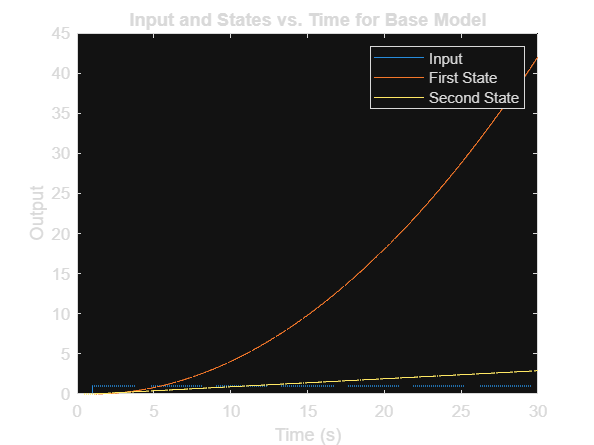

figure
plot(out_base.tout, out_base.input, ...
    out_base.tout, out_base.ybar)
xlabel("Time (s)")
ylabel("Output")
title("Input and States vs. Time for Base Model")
legend("Input", "First State", "Second State")

## Task 2

### Design a LQR

Q = eye(2);
R = 1;

syms P1 P2 P3
P = [P1 P2; P2 P3];
assume(P1, "positive")
assume(P2, "positive")
assume(P3, "positive")

% Matrix Ricatti Equation
P_dot = -P*A - A'*P + P*B*inv(R)*B'*P - Q;

% For LQR, solve for P when P_dot = 0
[P1_sol, P2_sol, P3_sol] = solve(P_dot == 0, [P1, P2, P3]);
P_sol = [P1_sol P2_sol; P2_sol P3_sol];

% Gain Equation
K_lqr = double(inv(R)*B'*P_sol);

### Implement LQR in Simulink for a Unit Step Input

out_lqr = runModel("LQR");

## Task 2

### Figures

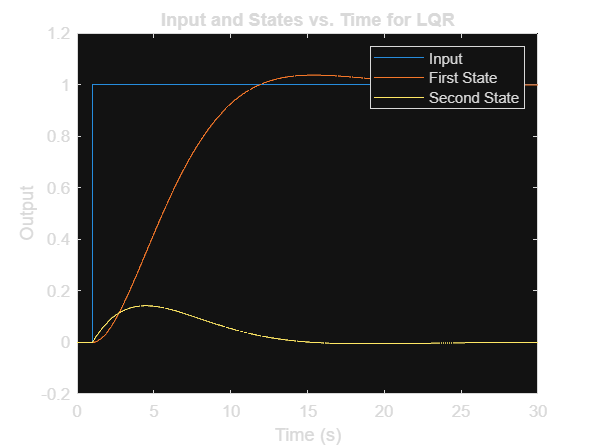

figure
plot(out_lqr.tout, out_lqr.input, ...
    out_lqr.tout, out_lqr.ybar)
xlabel("Time (s)")
ylabel("Output")
title("Input and States vs. Time for LQR")
legend("Input", "First State", "Second State")

## Task 3

### Design a LQC with an End Time of 30 Seconds

Q = eye(2);
R = 1;
S_f = [100 0; 0 100];

[~, ~, P_struct, ~, ~, ~] = matint(30, 0, S_f);

mult_lqc = inv(R)*B';

### Implement LQC in Simulink for a Unit Step Input

out_lqc = runModel("LQC");

## Task 3

### Figures

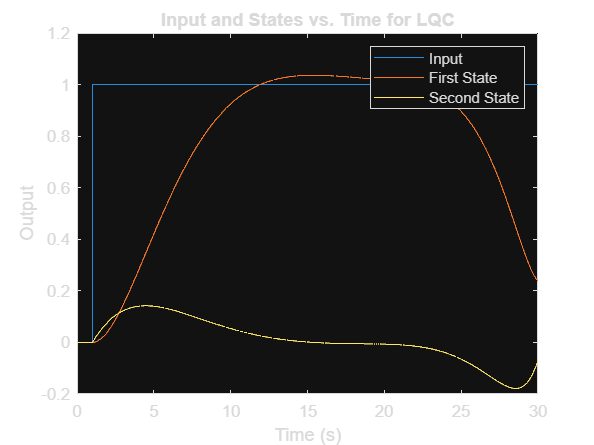

figure
plot(out_lqc.tout, out_lqc.input, ...
    out_lqc.tout, out_lqc.ybar)
xlabel("Time (s)")
ylabel("Output")
title("Input and States vs. Time for LQC")
legend("Input", "First State", "Second State")